save final.mlx OverallGlobalTemps2 


num = 0;
var = zeros(1,181);
date = zeros(1,181);
for j = 1:181
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
        for i = a:b
        num = num + OverallGlobalTemps2{i,2};
        end
    ave = num/12;
    num = 0;
    date(j) = j + 1834;
    var(j) = ave;
end
Goodietable69(:,1) = array2table(date');
Goodietable69(:,2) = array2table(var')

Goodietable69 = 181×2 table
    Var1     Var2 
    ____    ______

    1835    7.3925
    1836    7.6958
    1837    7.3757
    1838    7.5149
    1839    7.6322
    1840    7.7963
    1841    7.6882
    1842    8.0228
    1843    8.1737
    1844    7.6463
    1845    7.8512
    1846    8.5527
    1847     8.086
    1848    7.9795
    1849    7.9844
    1850    7.9007


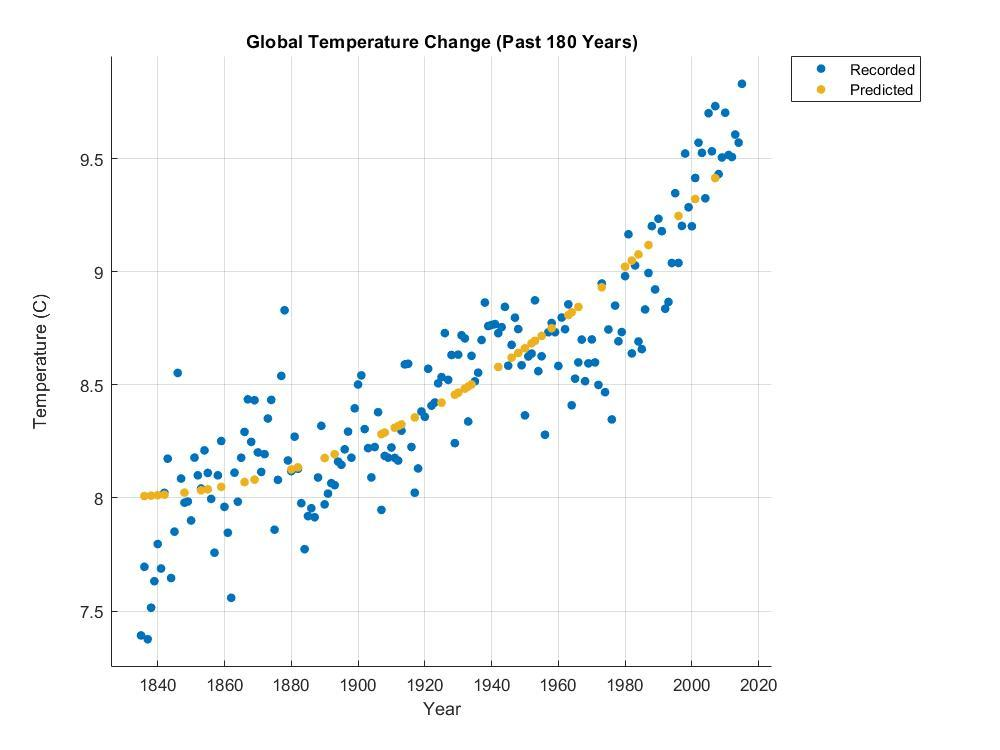

The predicted plot of the next hundred years looks like this:

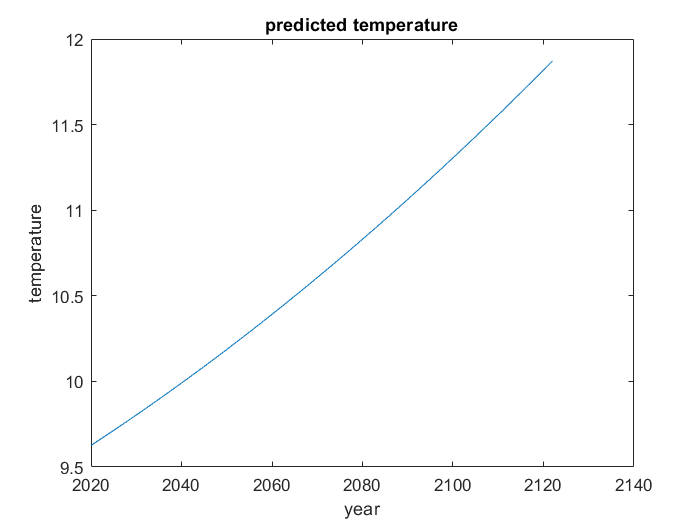

x1=[2020:2122];
y1=yfit;
xlabel('year');
ylabel('temperature');
title('predicted temperature');

temp = input('Enter a Year You Would Like to Know the Global Temperature of: ');

xlswrite('Actualdata.xlsx',temp);
yeet = readtable('Actualdata.xlsx');
yfit1 = trainedModel14.predictFcn(yeet);
fprintf('The Predicted Temp is %0.2f C',yfit1);

The Predicted Temp is 9.63 C

CountryData

US Predictor

num = 0;
var = zeros(1,168);
date = zeros(1,168);
for j = 1:168
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
    for i = a:b
        num = num + CountryData{i,1};
    end
    ave = num/12;
    num = 0;
    date(j) = j + 1844;
    var(j) = ave;
end
USdata1(:,1) = array2table(date');
USdata1(:,2) = array2table(var')

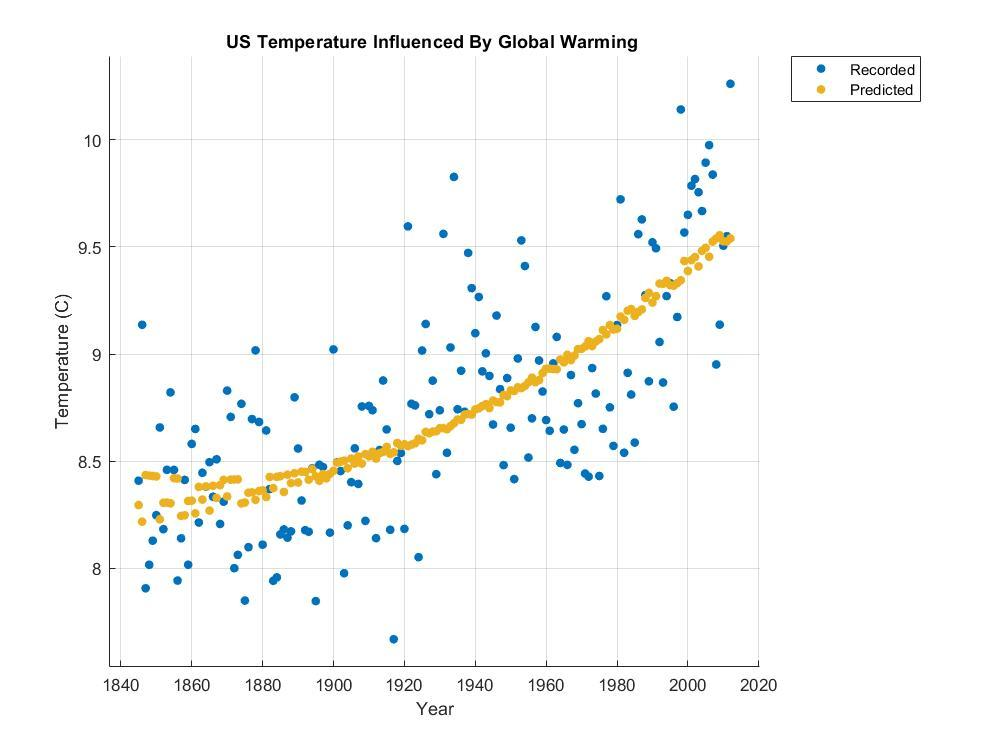

UK Predictor

num = 0;
var = zeros(1,168);
date = zeros(1,168);
for j = 1:168
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
    for i = a:b
        num = num + CountryData{i,2};
    end
    ave = num/12;
    num = 0;
    date(j) = j + 1844;
    var(j) = ave;
end
UKdata1(:,1) = array2table(date');
UKdata1(:,2) = array2table(var')

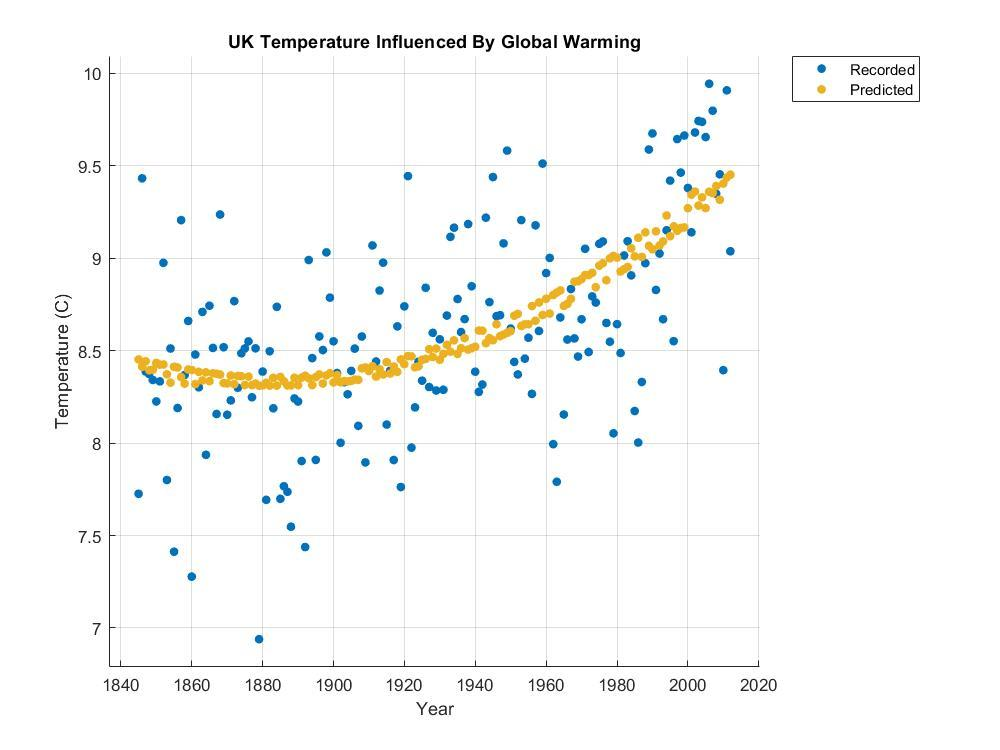

France Predictor

num = 0;
var = zeros(1,168);
date = zeros(1,168);
for j = 1:168
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
    for i = a:b
        num = num + CountryData{i,3};
    end
    ave = num/12;
    num = 0;
    date(j) = j + 1844;
    var(j) = ave;
end
Francedata1(:,1) = array2table(date');
Francedata1(:,2) = array2table(var')

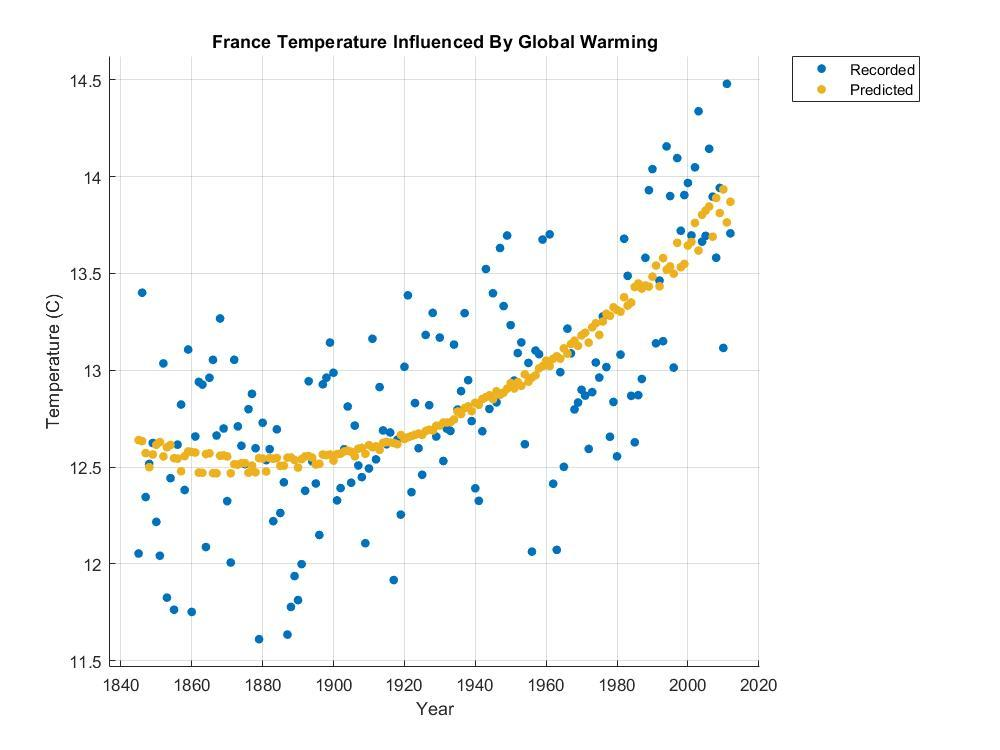

China Predictor

num = 0;
var = zeros(1,168);
date = zeros(1,168);
for j = 1:168
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
    for i = a:b
        num = num + CountryData{i,4};
    end
    ave = num/12;
    num = 0;
    date(j) = j + 1844;
    var(j) = ave;
end
Chinadata1(:,1) = array2table(date');
Chinadata1(:,2) = array2table(var')

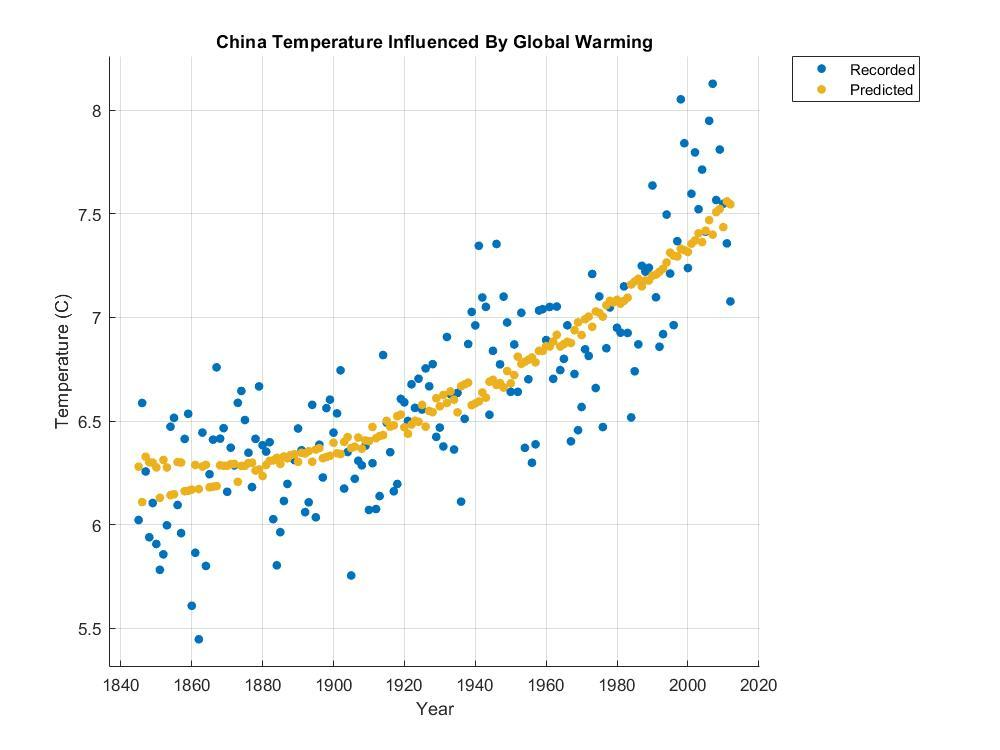

Russia Predictor

num = 0;
var = zeros(1,168);
date = zeros(1,168);
for j = 1:168
    if j == 1
        a = 1;
        b = 12;
    else
        a = (12*(j-1)) + 1;
        b = 11 + a;
    end
    for i = a:b
        num = num + CountryData{i,5};
    end
    ave = num/12;
    num = 0;
    date(j) = j + 1844;
    var(j) = ave;
end
Russiadata1(:,1) = array2table(date');
Russiadata1(:,2) = array2table(var')

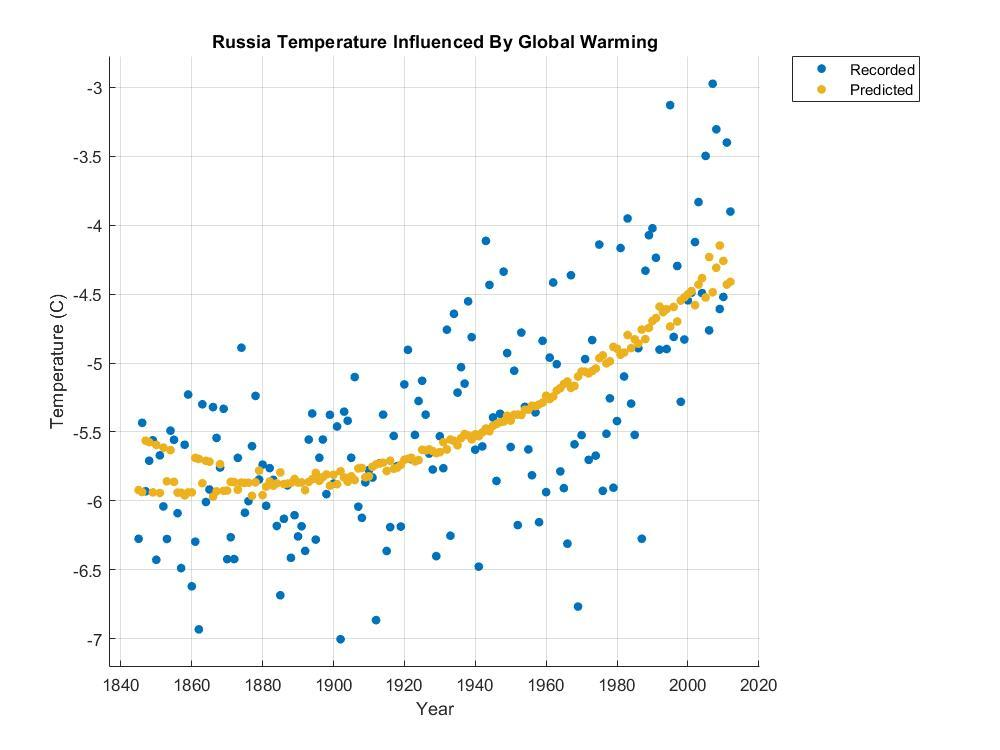

country = {'US'; 'UK'; 'France'; 'China'; 'Russia'};
ques = menu('Please Select a Country: ', country(1), country(2), country(3), country(4), country(5));
switch ques
    case 1
    US = input('Enter a Year You Would Like to Know the Temp for this country: ');
    xlswrite('Actualdata.xlsx', US);
    yeet = readtable('Actualdata.xlsx');
    yfit1 = trainedModelUS.predictFcn(yeet);
    case 2
    UK = input('Enter a Year You Would Like to Know the Temp for this country: ');
    xlswrite('Actualdata.xlsx', UK);
    yeet = readtable('Actualdata.xlsx');
    yfit1 = trainedModelUS.predictFcn(yeet);
    case 3
    France = input('Enter a Year You Would Like to Know the Temp for this country: ');
    xlswrite('Actualdata.xlsx', France);
    yeet = readtable('Actualdata.xlsx');
    yfit1 = trainedModelUS.predictFcn(yeet);
    case 4
    China = input('Enter a Year You Would Like to Know the Temp for this country: ');
    xlswrite('Actualdata.xlsx', China);
    yeet = readtable('Actualdata.xlsx');
    yfit1 = trainedModelUS.predictFcn(yeet);
    otherwise 
    Russia = input('Enter a Year You Would Like to Know the Temp for this country: ');
    xlswrite('Actualdata.xlsx', Russia);
    yeet = readtable('Actualdata.xlsx');
    yfit1 = trainedModelUS.predictFcn(yeet);
end
fprintf('The predicted temperature is %.2f C',yfit1);
